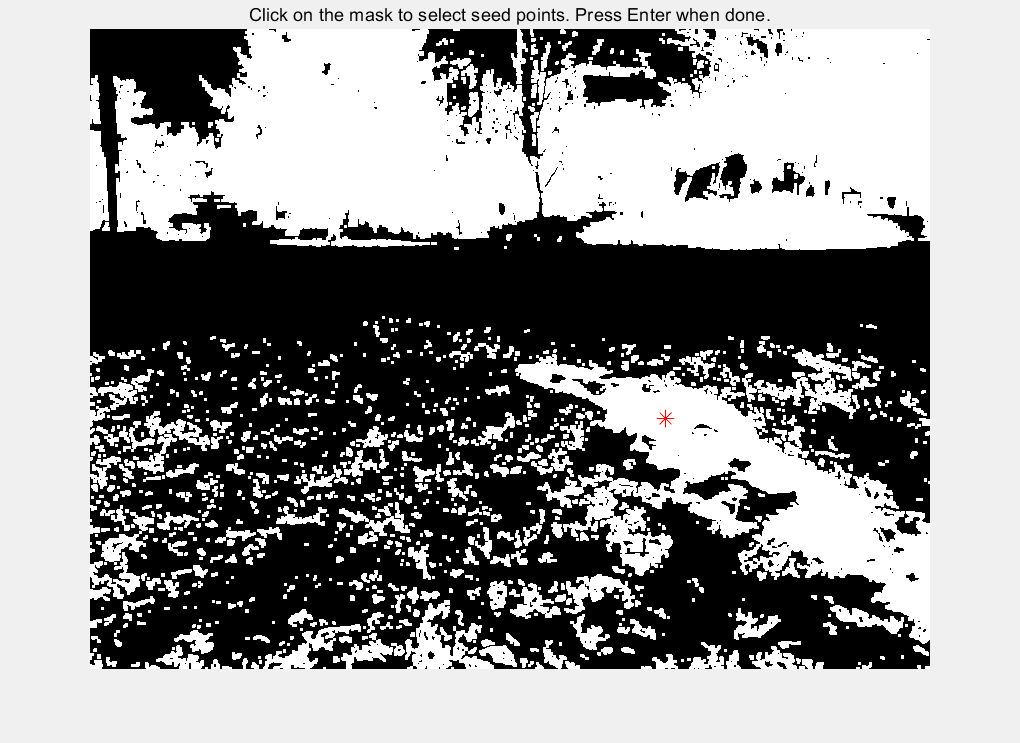

% 读取原始图像和生成初始掩码
or_img = imread('../resources/_MG_8675.jpg');
y_cb_cr_img = rgb2ycbcr(or_img);
y_channel = y_cb_cr_img(:, :, 1); 
y_mean = mean(y_channel(:));
y_std = std(double(y_channel(:)));
%threshold = y_mean;
threshold = y_mean - (y_std / 10);
shadow_mask = y_channel < threshold;  % 二值掩码
se = strel('square', 3);  % 定义一个 6x6 的结构元素
open_mask = imopen(shadow_mask, se);  % 开运算去除噪声


% 显示初始掩码并提示用户选择点
figure;
imshow(open_mask, []);
title('Click on the mask to select seed points. Press Enter when done.');
hold on;

% 交互式获取用户点击的基础点
[x, y] = ginput();  % 用户点击坐标
x = round(x);       % 转换为整数索引
y = round(y);

% 验证用户选择的点是否在图像范围内
[h, w] = size(open_mask);
valid_points = (x > 0 & x <= w) & (y > 0 & y <= h);  % 有效点
x = x(valid_points);
y = y(valid_points);

% 在图像上标记用户选择的基础点
plot(x, y, 'r*', 'MarkerSize', 10);

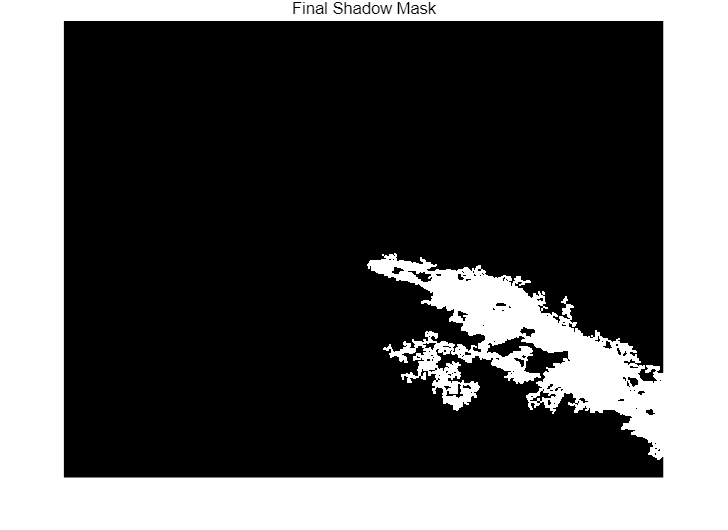

% 创建最终掩码，初始化为 0
final_mask = false(size(open_mask));

% 区域增长逻辑
se = strel('square', 3);  % 定义膨胀结构元素
for i = 1:length(x)
    seed = false(size(open_mask));  % 创建种子点掩码
    seed(y(i), x(i)) = true;          % 设置基础点为种子
    region = seed;                    % 初始化区域

    % 扩张，直到区域稳定
    while true
        dilated = imdilate(region, se);    % 膨胀操作
        new_region = dilated & open_mask; % 限制在初始掩码范围内
        if isequal(new_region, region)     % 如果区域没有变化，则退出
            break;
        end
        region = new_region;               % 更新区域
    end

    % 合并当前点的区域到最终掩码
    final_mask = final_mask | region;
end

% 显示最终掩码
figure;
imshow(final_mask, []);
title('Final Shadow Mask');